# PV Models

clear;
close all;
[param, weather, route, driver] = loadData();

#### PV power vs ambient temperature

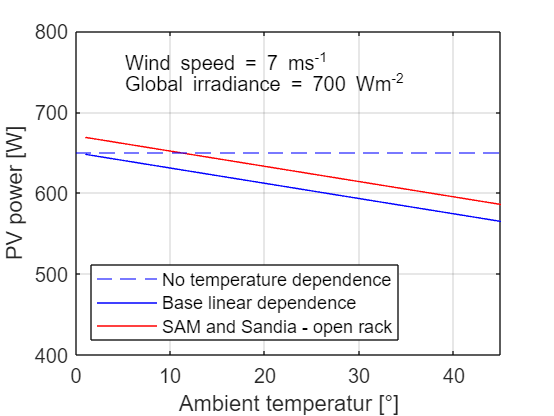

figure
tempAmb = linspace(1,45,3);
G = 700;
WS = 7;

PVpower = param.pv.area * G * param.pv.eff * param.pv.loss.total;

PVpower_basic                       = PVpower*(1 + param.pv.powerCoeff*tempAmb);
PVpower_Fainam                      = PVpower*(1 + param.pv.powerCoeff*(moduleTemperatureFainam(G,tempAmb,WS)                                        - param.pv.tempSTC));
PVpower_simple_Sandia_openRack      = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSandia(G,tempAmb,WS,"glass-cell-polymer","open rack")         - param.pv.tempSTC));
PVpower_simple_Sandia_insulatedBack = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSandia(G,tempAmb,WS,"glass-cell-polymer","insulated back")    - param.pv.tempSTC));
PVpower_NOCT                        = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureNOCT(G,tempAmb,WS,param.pv.eff)                               - param.pv.tempSTC));
PVpower_SOWA_NOCT                   = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSOWANOCT(G,tempAmb)                                           - param.pv.tempSTC));

yline(PVpower,'--b', 'DisplayName', 'No temperature dependence')
hold on
plot(tempAmb,PVpower_basic,'b', 'DisplayName', 'Base linear dependence')
% plot(tempAmb,PVpower_Fainam,'k', 'DisplayName', 'Fainam dependence')
plot(tempAmb,PVpower_simple_Sandia_openRack,'r', 'DisplayName', 'SAM and Sandia - open rack')
% plot(tempAmb,PVpower_simple_Sandia_insulatedBack,'--r', 'DisplayName', 'SAM and Sandia - insulated back')
% plot(tempAmb,PVpower_NOCT,'g', 'DisplayName', 'NOCT')
% plot(tempAmb,PVpower_SOWA_NOCT,'--g', 'DisplayName', 'SOWA NOCT')

clickableLegend
legend('Location', 'southwest')

xlabel("Ambient temperatur [°]")
ylabel("PV power [W]")
xlim([0 max(tempAmb)])
ylim([G-300 G+100])
grid on
box on
textName = ['Wind speed = ', num2str(WS), ' ms^{-1}'];
text(5,G+60,textName);
textName = ['Global irradiance = ', num2str(G), ' Wm^{-2}'];
text(5,G+35,textName);
hold off

#### PV power vs ambient temperature

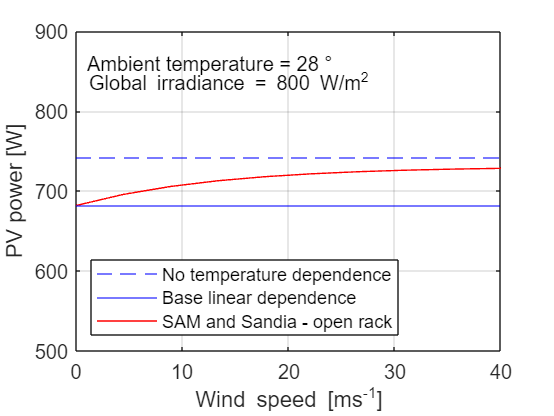

figure
tempAmb = 28;
G = 800;
WS = linspace(0,40,10);

PVpower = param.pv.area * G * param.pv.eff * param.pv.loss.total;

PVpower_basic                       = PVpower*(1 + param.pv.powerCoeff*tempAmb);
PVpower_Fainam                      = PVpower*(1 + param.pv.powerCoeff*(moduleTemperatureFainam(G,tempAmb,WS)                                        - param.pv.tempSTC));
PVpower_simple_Sandia_openRack      = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSandia(G,tempAmb,WS,"glass-cell-polymer","open rack")         - param.pv.tempSTC));
PVpower_simple_Sandia_insulatedBack = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSandia(G,tempAmb,WS,"glass-cell-polymer","insulated back")    - param.pv.tempSTC));
PVpower_NOCT                        = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureNOCT(G,tempAmb,WS,param.pv.eff)                               - param.pv.tempSTC));
PVpower_SOWA_NOCT                   = PVpower*(1 + param.pv.powerCoeff*(cellTemperatureSOWANOCT(G,tempAmb)                                           - param.pv.tempSTC));

yline(PVpower,'--b', 'DisplayName', 'No temperature dependence')
hold on
yline(PVpower_basic,'b', 'DisplayName', 'Base linear dependence')
% plot(WS,PVpower_Fainam,'k', 'DisplayName', 'Fainam dependence')
plot(WS,PVpower_simple_Sandia_openRack,'r', 'DisplayName', 'SAM and Sandia - open rack')
% plot(WS,PVpower_simple_Sandia_insulatedBack,'--r', 'DisplayName', 'SAM and Sandia - insulated back')
% plot(WS,PVpower_NOCT,'g', 'DisplayName', 'NOCT')
% yline(PVpower_SOWA_NOCT,'--g', 'DisplayName', 'SOWA NOCT')

clickableLegend
legend('Location', 'southwest')

xlabel("Wind speed [ms^{-1}]")
ylabel("PV power [W]")
xlim([0 max(WS)])
ylim([G-300 G+100])
grid on
box on
textName = ['Ambient temperature = ', num2str(tempAmb), ' °'];
text(1,G+60,textName);
textName = ['Global irradiance = ', num2str(G), ' W/m^2'];
text(1,G+35,textName);
hold off